First I need to agree what is computed to generate the random numbers.

I will describe a few constants

- timesteps (bit length of output)

- the initial seed needs to be atleast timesteps*2 + 1 length, so needs to be greater than 1

- start state (which will just be one in the middle for now)

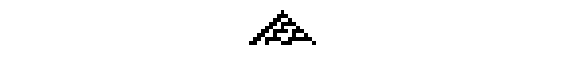

rule30 = [0  0  0  1  1  1  1  0];
seed_radius = 64;
timesteps = 8; % 8 bit fraction from middle row
start_state = [zeros(1, seed_radius) 1 zeros(1, seed_radius)];
eca_visualize(eca_run(start_state, rule30, timesteps), 2000)

Now let's see what precision I get for converting numbers to binary

format long
col = eca_run_middle_column(start_state, rule30, timesteps)

col =      1     1     0     1     1     1     0     1


all8 = binary_to_fraction(col(1, 1:8))

all8 =    0.863281250000000


format default